% freq10.0 每波长24个单元
% freq4.0 每波长60个单元
%定义介质参数
w = linspace(2e6,2.2e6,11).';
%coefficient1=zeros(6,2);
%coefficient2=zeros(5,4);
p1=zeros(11,1);
p2=zeros(11,1);
%for ii=1:11
Rho = 2700;%密度
cT = 3263;
H = 2.38e-3; % 板厚
f=1e6;
curOmega = 2*pi*f;
Miu = Rho*cT^2;%泊松比
kT = curOmega/cT;

N_ind = 10;
arrN_ind = 0:1:2*N_ind-1;
arr_K1 = (kT^2 - (arrN_ind*pi/(2*H)).^2).^0.5;
nPropMode = length(find(real(arr_K1)>0)); % 传播模态总数
WavLen = 2*pi/arr_K1(1);

Nelem = 40; %每个波长的单元个数
Nwl = 20;
r = 50.8e-3;%内圈半径
R = r+2*H;%外圈半径
rr= 0.5*(r+R);
a = 1*pi/2;%弯曲角度

nGauss = 4;
x1=-0.339981043584856;
x2=0.339981043584856;
x3=-0.861136311594053;
x4=0.861136311594053;
w1=0.652145154862546;
w2=0.652145154862546;
w3=0.347854845137454;
w4=0.347854845137454;
arrW = [w1,w2,w3,w4];
arrX = [x1,x2,x3,x4];


[MidPoint,midPoint,ElemLen,elemLen,NormalVector,normalVector,arrIndex,MarkB,LenExtend,...
ElemLen_m_power,ElemLen_p_power,MidPoint_m_power,MidPoint_p_power,NormalVector_m_power,...
NormalVector_p_power,ElemLen_power]=ElemMesh_MainFrame_LS_Green_four(H,WavLen,Nelem,Nwl,a,R,r);

[mat_r,mat_dr_D_dn,MidPoint_M,ElemLen_M,NormalVector_M,midPoint_M,elemLen_M,normalVector_M,arrIndex_M]...
=SUB_GeneGeoInfoNew_LS_Green_four(arrX,MidPoint,ElemLen,NormalVector,midPoint,elemLen,normalVector,arrIndex);

[T,G]=GeneMat_four(mat_r,mat_dr_D_dn,arrW,ElemLen_M,kT,Miu);

[arrRes]= total_JS_Green_II_four(MidPoint_M,NormalVector_M,midPoint_M,normalVector_M,...
arrIndex_M,cT,Miu,H,curOmega,nPropMode,MarkB,T,G,rr);
u1=arrRes(arrIndex_M(1)+1:arrIndex_M(2));
u2=arrRes(arrIndex_M(4)+1:arrIndex_M(5));
[p_G,p_MG,p_PG]=power_Gauss4(arrRes,arrIndex_M,cT,Miu,H,curOmega,nPropMode,ElemLen_m_power,...
ElemLen_p_power,MidPoint_m_power,MidPoint_p_power,NormalVector_m_power,NormalVector_p_power,arrW,arrX,rr);
%{
[p_m,p_p,p_m_p]=power_1(arrRes,arrIndex_M,Miu,Rho,H,curOmega,nPropMode,ElemLen_m_power,...
ElemLen_p_power,MidPoint_m_power,MidPoint_p_power,NormalVector_m_power,NormalVector_p_power,r);
%}
%if ii<7
%coefficient1(ii,:)=arrRes(arrIndex_M(6)+1:arrIndex_M(6)+2*nPropMode);
%elseif ii>=7
%coefficient2(ii-6,:)=arrRes(arrIndex_M(6)+1:arrIndex_M(6)+2*nPropMode);
%end
ii=1;
p1(ii)=-p_MG/p_G;
p2(ii)=-p_PG/p_G;
disp(p1)

   1.0e-30 *

    0.1386
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



disp(p2)

   1.0e-30 *

    0.1362
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



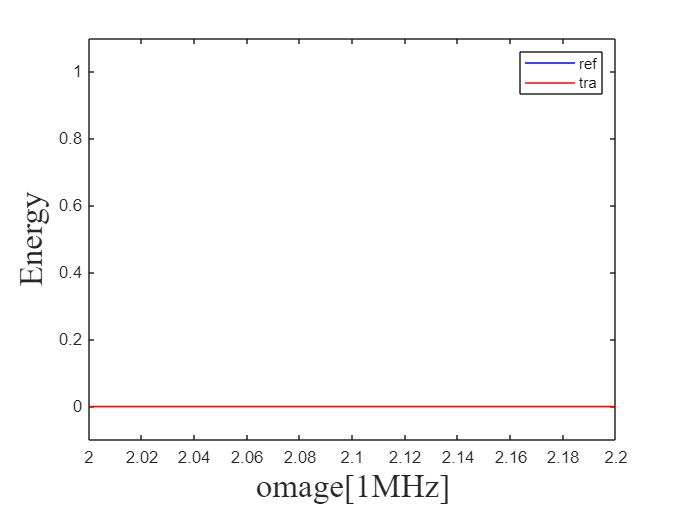

%end
fff=w*1e-6;
%ffff=w(7:11)*1e-6;
%{
xxxx1=asin(MidPoint(arrIndex_M(1)+1:arrIndex_M(2))/R);
xxxx2=asin(MidPoint(arrIndex_M(4)+1:arrIndex_M(5))/r);
figure(1)
plot(xxxx1,real(u1),'b',xxxx1,imag(u1),'b--')
ylabel('\it{u}','FontName','Times New Roman','FontSize',20)
xlabel('\it{arcsin(x/R)}','FontName','Times New Roman','FontSize',20)
legend('ref','tra'); 
hold on
figure(2)
plot(xxxx2,real(u2),'r',xxxx2,imag(u2),'r--')
ylabel('\it{u}','FontName','Times New Roman','FontSize',20)
xlabel('\it{arcsin(x/r)}','FontName','Times New Roman','FontSize',20)
legend('real','imag'); 
hold on
%}

figure(1)
plot(fff,p1,'b',fff,p2,'r')
ylabel('\it{Energy}','FontName','Times New Roman','FontSize',20)
xlabel('\it{omage[1MHz]}','FontName','Times New Roman','FontSize',20)
legend('ref','tra'); 
axis([2,2.2,-0.1,1.1])
set(gca,'XTick',[2:0.02:2.2])
hold on


%{
coefficient11=[coefficient1(:,1:2);coefficient2(:,1),coefficient2(:,3)];
coefficient22=[coefficient2(:,2),coefficient2(:,4)];
figure(1)
plot(fff,real(coefficient11(:,1)),'-*b',fff,imag(coefficient11(:,1)),'-ob',ffff,real(coefficient22(:,1)),'-*r',ffff,imag(coefficient22(:,1)),'-or')
ylabel('\it{Mode coefficient[R-]}','FontName','Times New Roman','FontSize',20)
xlabel('\it{f[1MHz]}','FontName','Times New Roman','FontSize',20)
legend('MO real','MO imag','M1 real','M1 imag'); 
set(gca,'XTick',[1:0.2:3])
hold on
figure(2)
plot(fff,real(coefficient11(:,2)),'-*b',fff,imag(coefficient11(:,2)),'-ob',ffff,real(coefficient22(:,2)),'-*r',ffff,imag(coefficient22(:,2)),'-or')
ylabel('\it{Mode coefficient[R+]}','FontName','Times New Roman','FontSize',20)
xlabel('\it{f[1MHz]}','FontName','Times New Roman','FontSize',20)
legend('MO real','MO imag','M1 real','M1 imag'); 
set(gca,'XTick',[1:0.2:3])
hold on
%}
%{
x_plot_up = linspace(-LenExtend-R*a/2,LenExtend+R*a/2,arrIndex_M(3));
x_plot_low = linspace(-LenExtend-r*a/2,LenExtend+r*a/2,arrIndex_M(6)-arrIndex_M(3));
nPropMode_R = 1:2*nPropMode;


figure(1)
plot(x_plot_up,real(arrRes(1:arrIndex_M(3),:)),'b')
hold on
figure(2)
plot(x_plot_up,imag(arrRes(1:arrIndex_M(3),:)),'b--')
hold on
figure(3)
plot(x_plot_low,real(arrRes(arrIndex_M(3)+1:arrIndex_M(6),:)),'r')
hold on
figure(4)
plot(x_plot_low,imag(arrRes(arrIndex_M(3)+1:arrIndex_M(6),:)),'r--')
hold on
figure(5)
plot(nPropMode_I,real(arrRes(arrIndex_M(6)+1:arrIndex_M(6)+nPropMode,:)),'r')
hold on
plot(nPropMode_I,imag(arrRes(arrIndex_M(6)+1:arrIndex_M(6)+nPropMode,:)),'r--')
hold on
%}